# Opdacht 18 - Matlab fourier

## Auteur: Perijn Huijser

## Datum: 24-09-2025

## Opdracht

### Initialisatie

close all
clear

syms f(t) t F(omega)

### A) Stel de functieomschrjiving op van de functie

f(t) = piecewise( (t < 0), exp(2*t), t == 0, exp(0),  (t > 0), exp(-2*t) )

$$f(t) = \left\{ \begin{array}{cl} {\mathrm{e}}^{2\,t} & \text{ if }t<0\\ 1 & \text{ if }t=0\\ {\mathrm{e}}^{-2\,t} & \text{ if }0<t \end{array}\right.$$

### B) Teken de functie met fplot

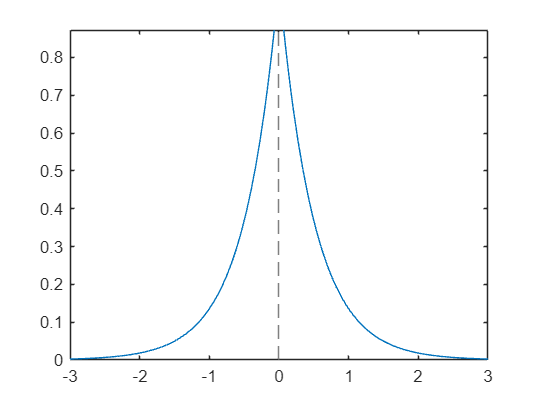

figure;

fplot(f, [-3 3])

### C) Bepaal de Fourier-getransformeerde van f(t)

assume(omega, 'integer')
F(omega) =  int(f * exp(1i*omega*t), t, -inf, inf)

$$F(omega) = -\frac{1}{-2+\omega \,\mathrm{i}}+\frac{1}{2+\omega \,\mathrm{i}}$$

### D) Vereenvoudig de  fouriergetransformeerde

F = simplify(F)

$$F(omega) = \frac{4}{\omega^{2}+4}$$

### E) Teken de bij 'D' bepaalde Fourier-getransformeerde van f(t)

F(1:7)

$$ans = \left(\begin{array}{ccccccc} \frac{4}{5} & \frac{1}{2} & \frac{4}{13} & \frac{1}{5} & \frac{4}{29} & \frac{1}{10} & \frac{4}{53} \end{array}\right)$$

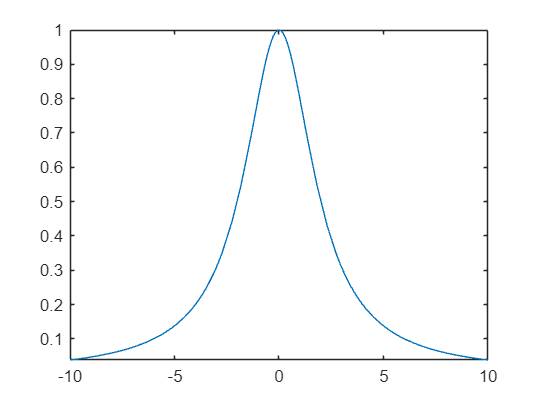


figure;
fplot(F, [-10 10])